# The stereoscopy exercise.

This exercise is done in colaboration with Hennah Terborg

## Read and show and image:

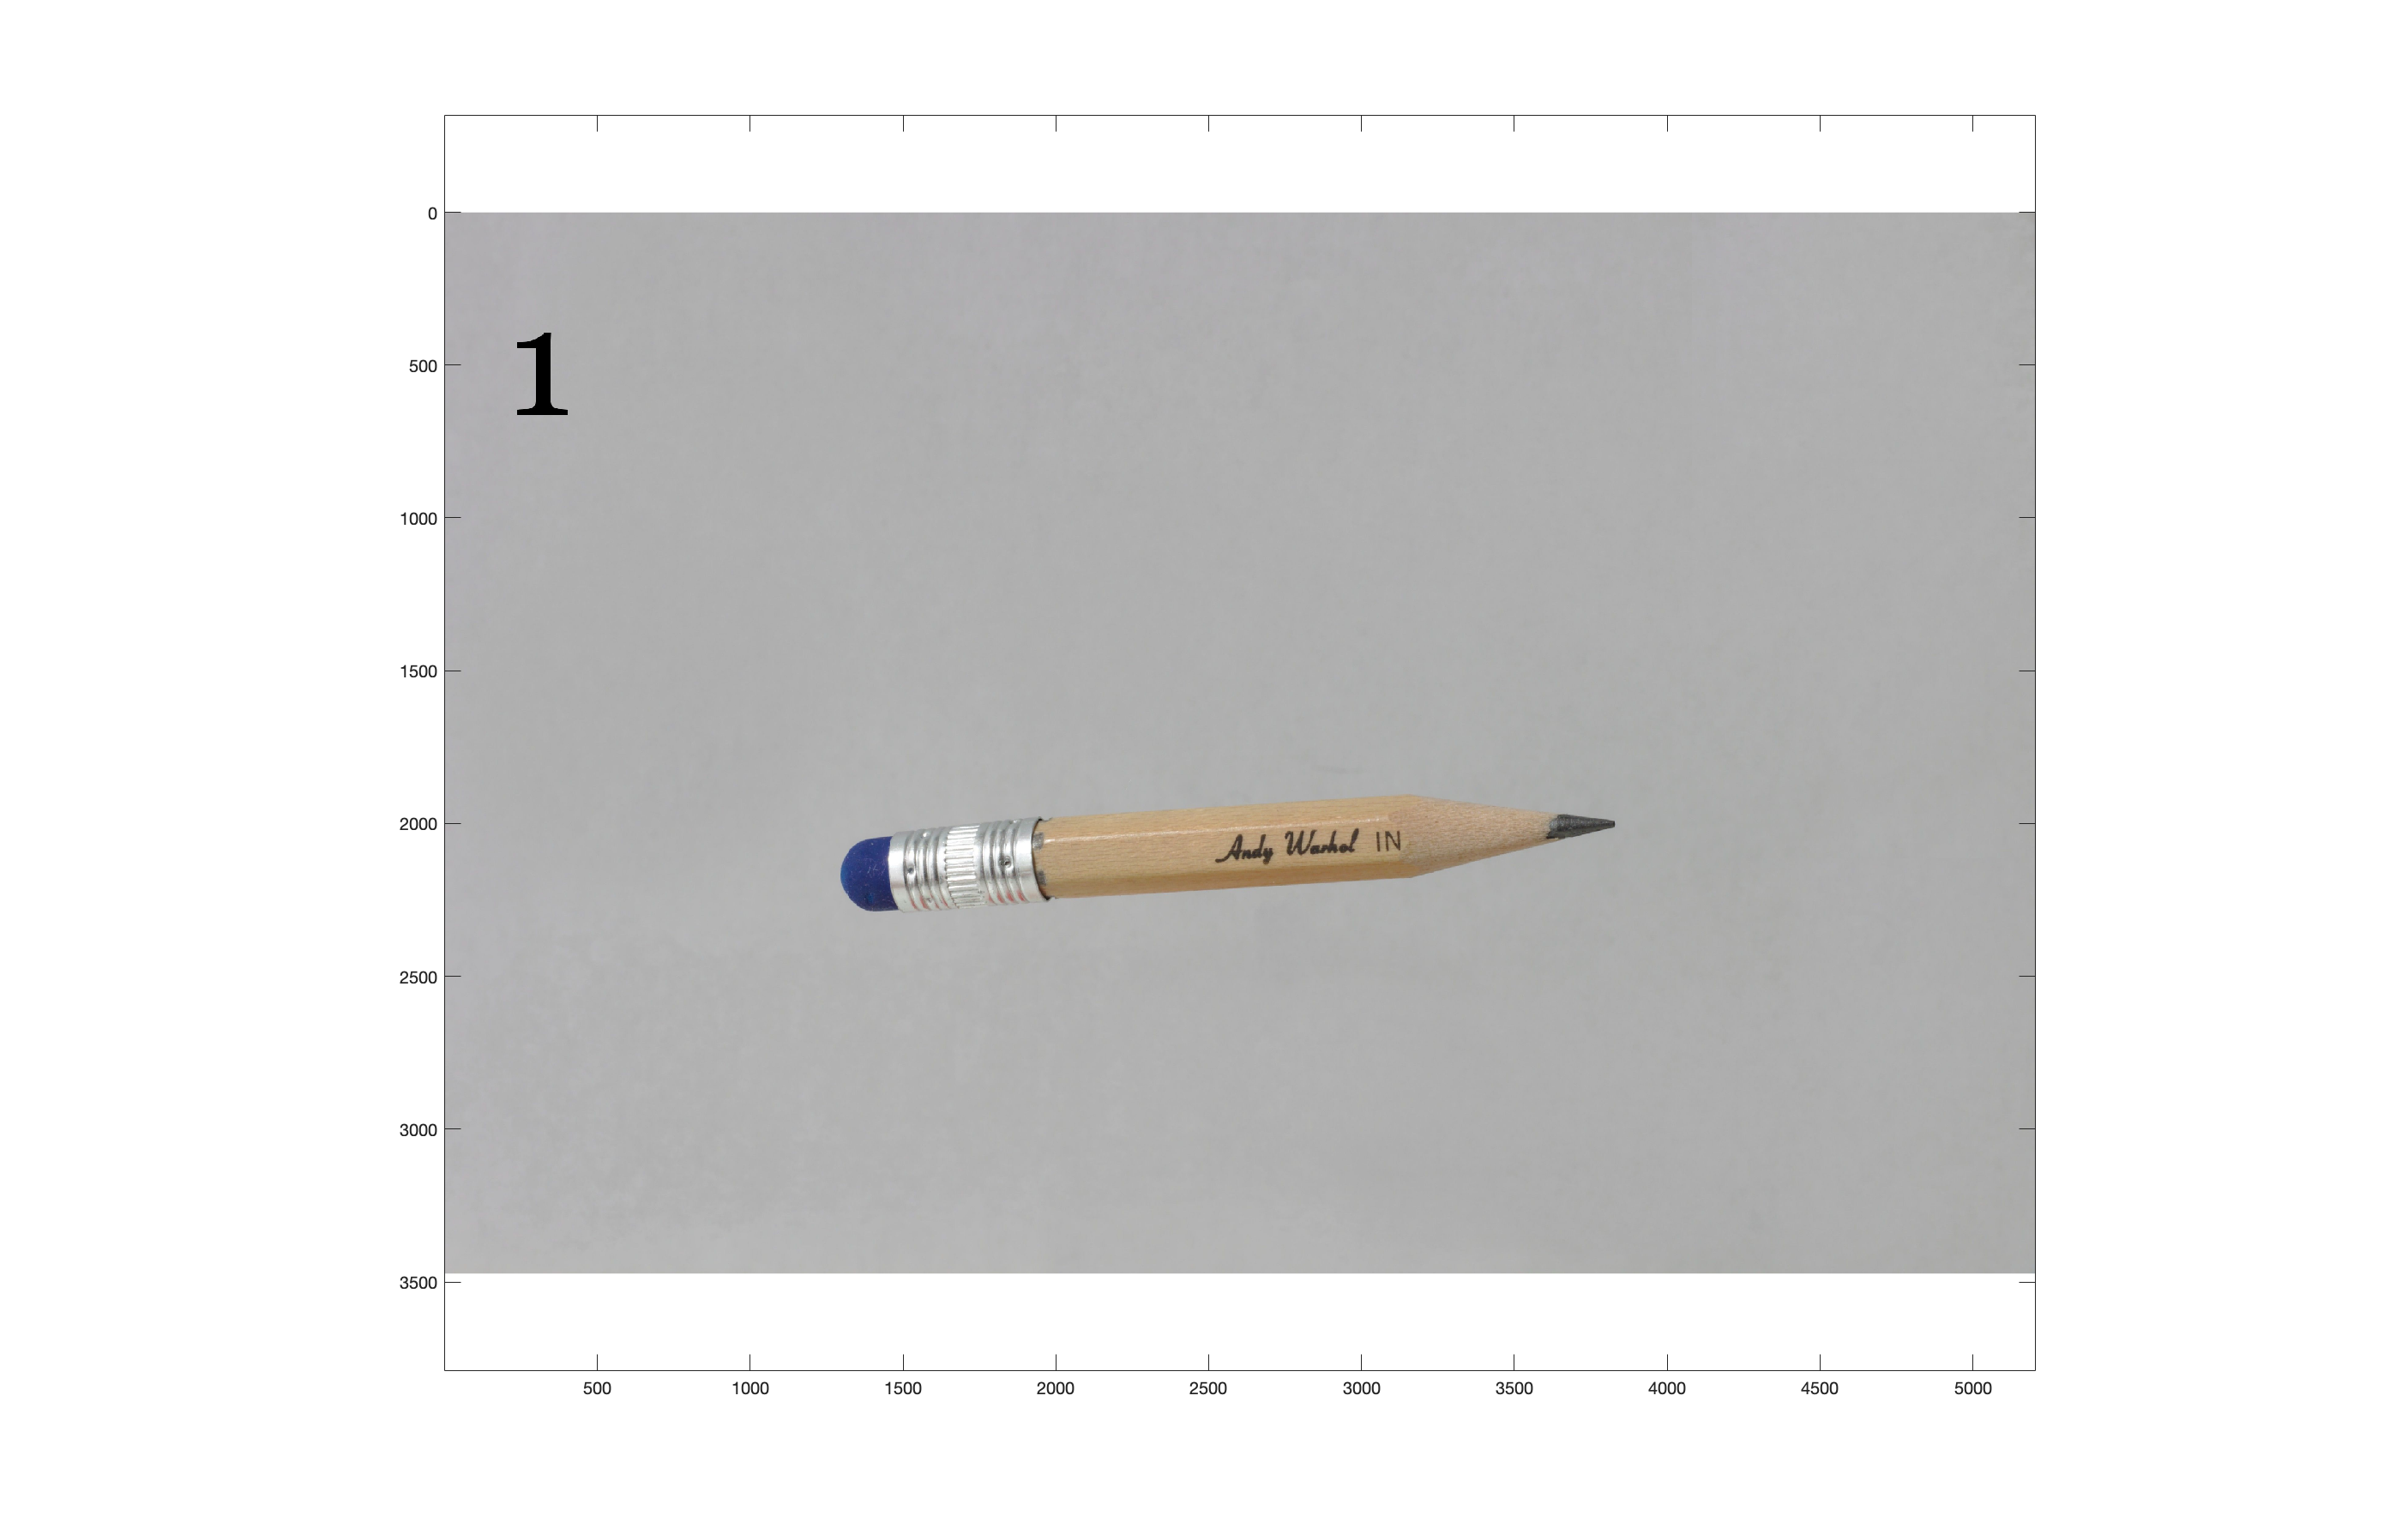

image_left = imread('C1.jpg'); % Read the 1 image from a file
h1=figure(1); % Create a new figure.
clf;
imagesc(image_left); % Plot an image.
axis('equal'); % Do not distort x and y axes.

% For capturing the pixel coordinates ginput() might be useful. Use of ginput()
% is easier, if you make the image a bit larger:
set(h1,'position',[0 100 1400 900]);

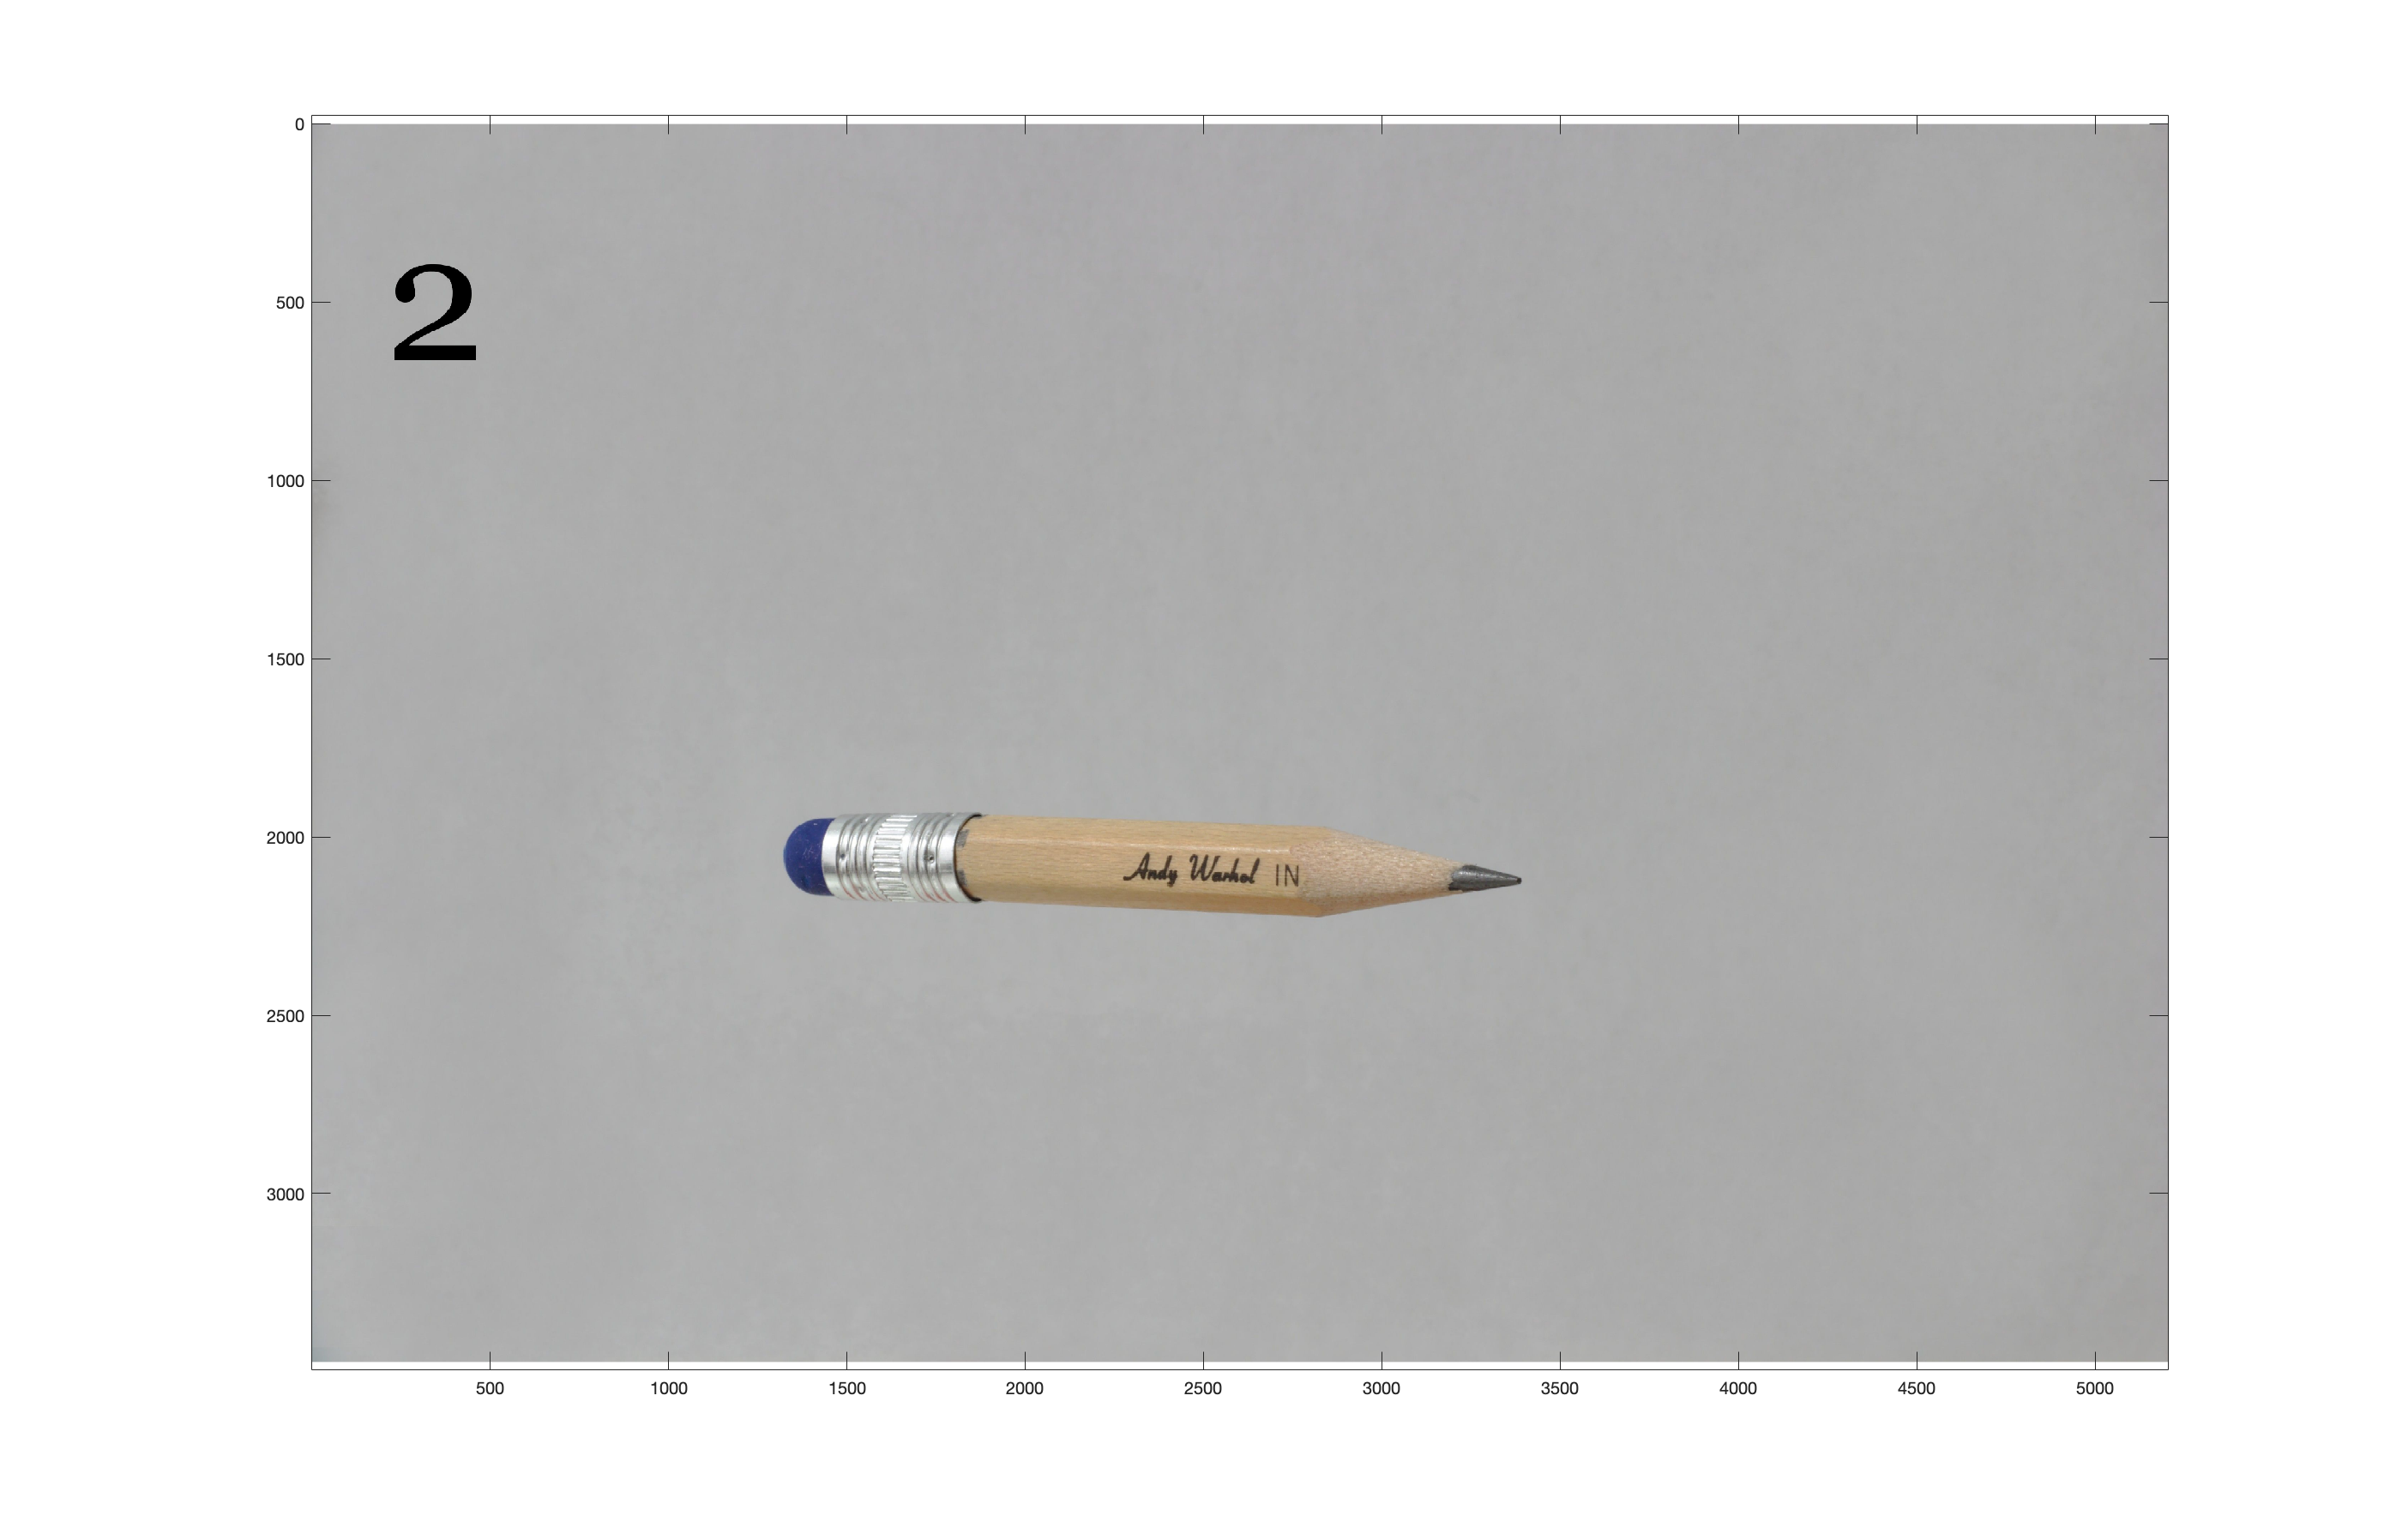


image_right = imread('C2.jpg'); % Read the 2 image from a file
h2=figure(1); % Create a new figure.
clf;
imagesc(image_right); % Plot an image.
axis('equal'); % Do not distort x and y axes.


% For capturing the pixel coordinates ginput() might be useful. Use of ginput()
% is easier, if you make the image a bit larger:
set(h2,'position',[0 100 1400 900]);

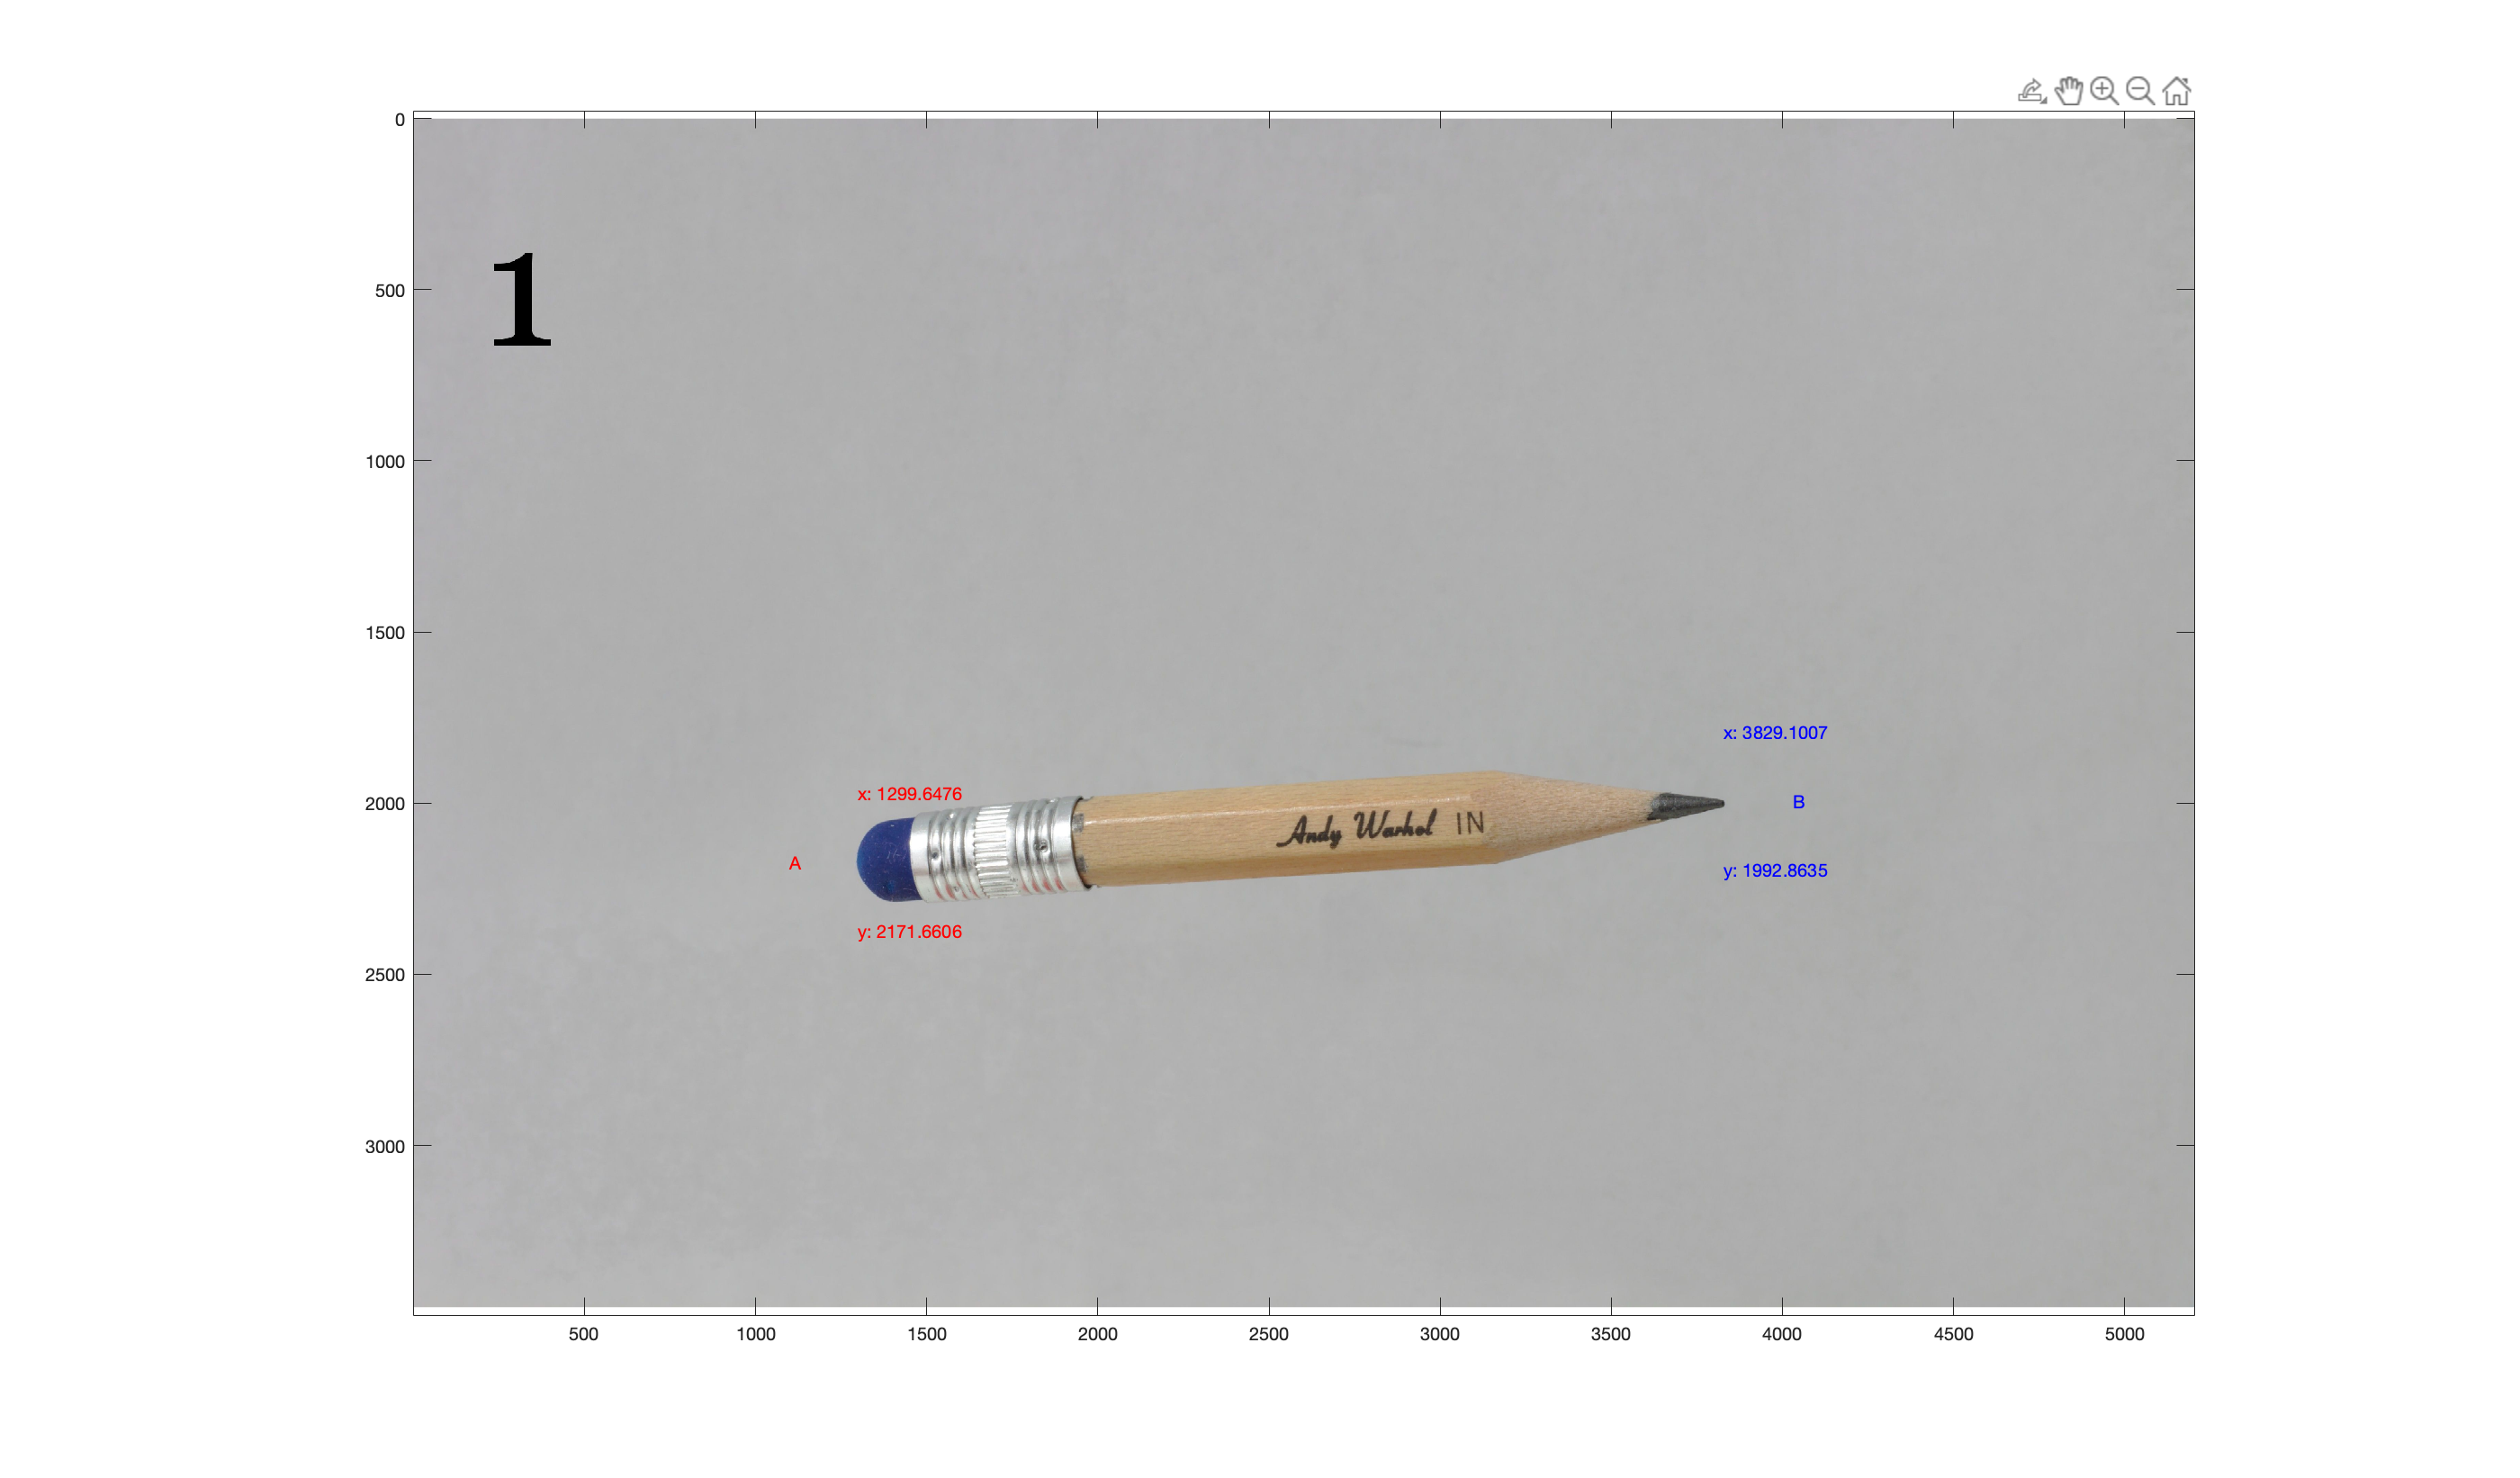

image_left = imread('C1.jpg'); % Read the 1 image from a file
h1=figure(1); % Create a new figure.
clf;
imagesc(image_left); % Plot an image.
axis('equal'); % Do not distort x and y axes.

% For capturing the pixel coordinates ginput() might be useful. Use of ginput()
% is easier, if you make the image a bit larger:
set(h1,'position',[0 100 1400 900]);

% Here pixel coordinates of 2 ends of the pensil from the first image are
% found
% x_pixel_A_1 - x pixel coordinate of A end of the pensil from the 1 image
% y_pixel_A_1 - y pixel coordinate of A end of the pensil from the 1 image
[x_pixel_A_1, y_pixel_A_1] = ginput(1);
text_x_str_A_1 = ['x: ' num2str(x_pixel_A_1)];
text_y_str_A_1 = ['y: ' num2str(y_pixel_A_1)];
text(x_pixel_A_1 - 200, y_pixel_A_1, 'A', 'Color', 'r');
text(x_pixel_A_1, y_pixel_A_1 - 200, text_x_str_A_1, 'Color', 'r');
text(x_pixel_A_1, y_pixel_A_1 + 200, text_y_str_A_1, 'Color', 'r');

% x_pixel_B_1 - x pixel coordinate of B end of the pensil from the 1 image
% y_pixel_B_1 - y pixel coordinate of B end of the pensil from the 1 image
[x_pixel_B_1, y_pixel_B_1] = ginput(1);
text_x_str_B_1 = ['x: ' num2str(x_pixel_B_1)];
text_y_str_B_1 = ['y: ' num2str(y_pixel_B_1)];
text(x_pixel_B_1 + 200, y_pixel_B_1, 'B', 'Color', 'b');
text(x_pixel_B_1, y_pixel_B_1 - 200, text_x_str_B_1, 'Color', 'b');
text(x_pixel_B_1, y_pixel_B_1 + 200, text_y_str_B_1, 'Color', 'b');

% Here the pixel coordinates of A and B ends of pensil from 1 image are converted 
% into camera's system coordinates

% camera coordinates of A end from 1 image
camera_A_1 = px2pos([x_pixel_A_1, y_pixel_A_1]);  
% camera coordinates of B end from 1 image
camera_B_1 = px2pos([x_pixel_B_1, y_pixel_B_1]); 


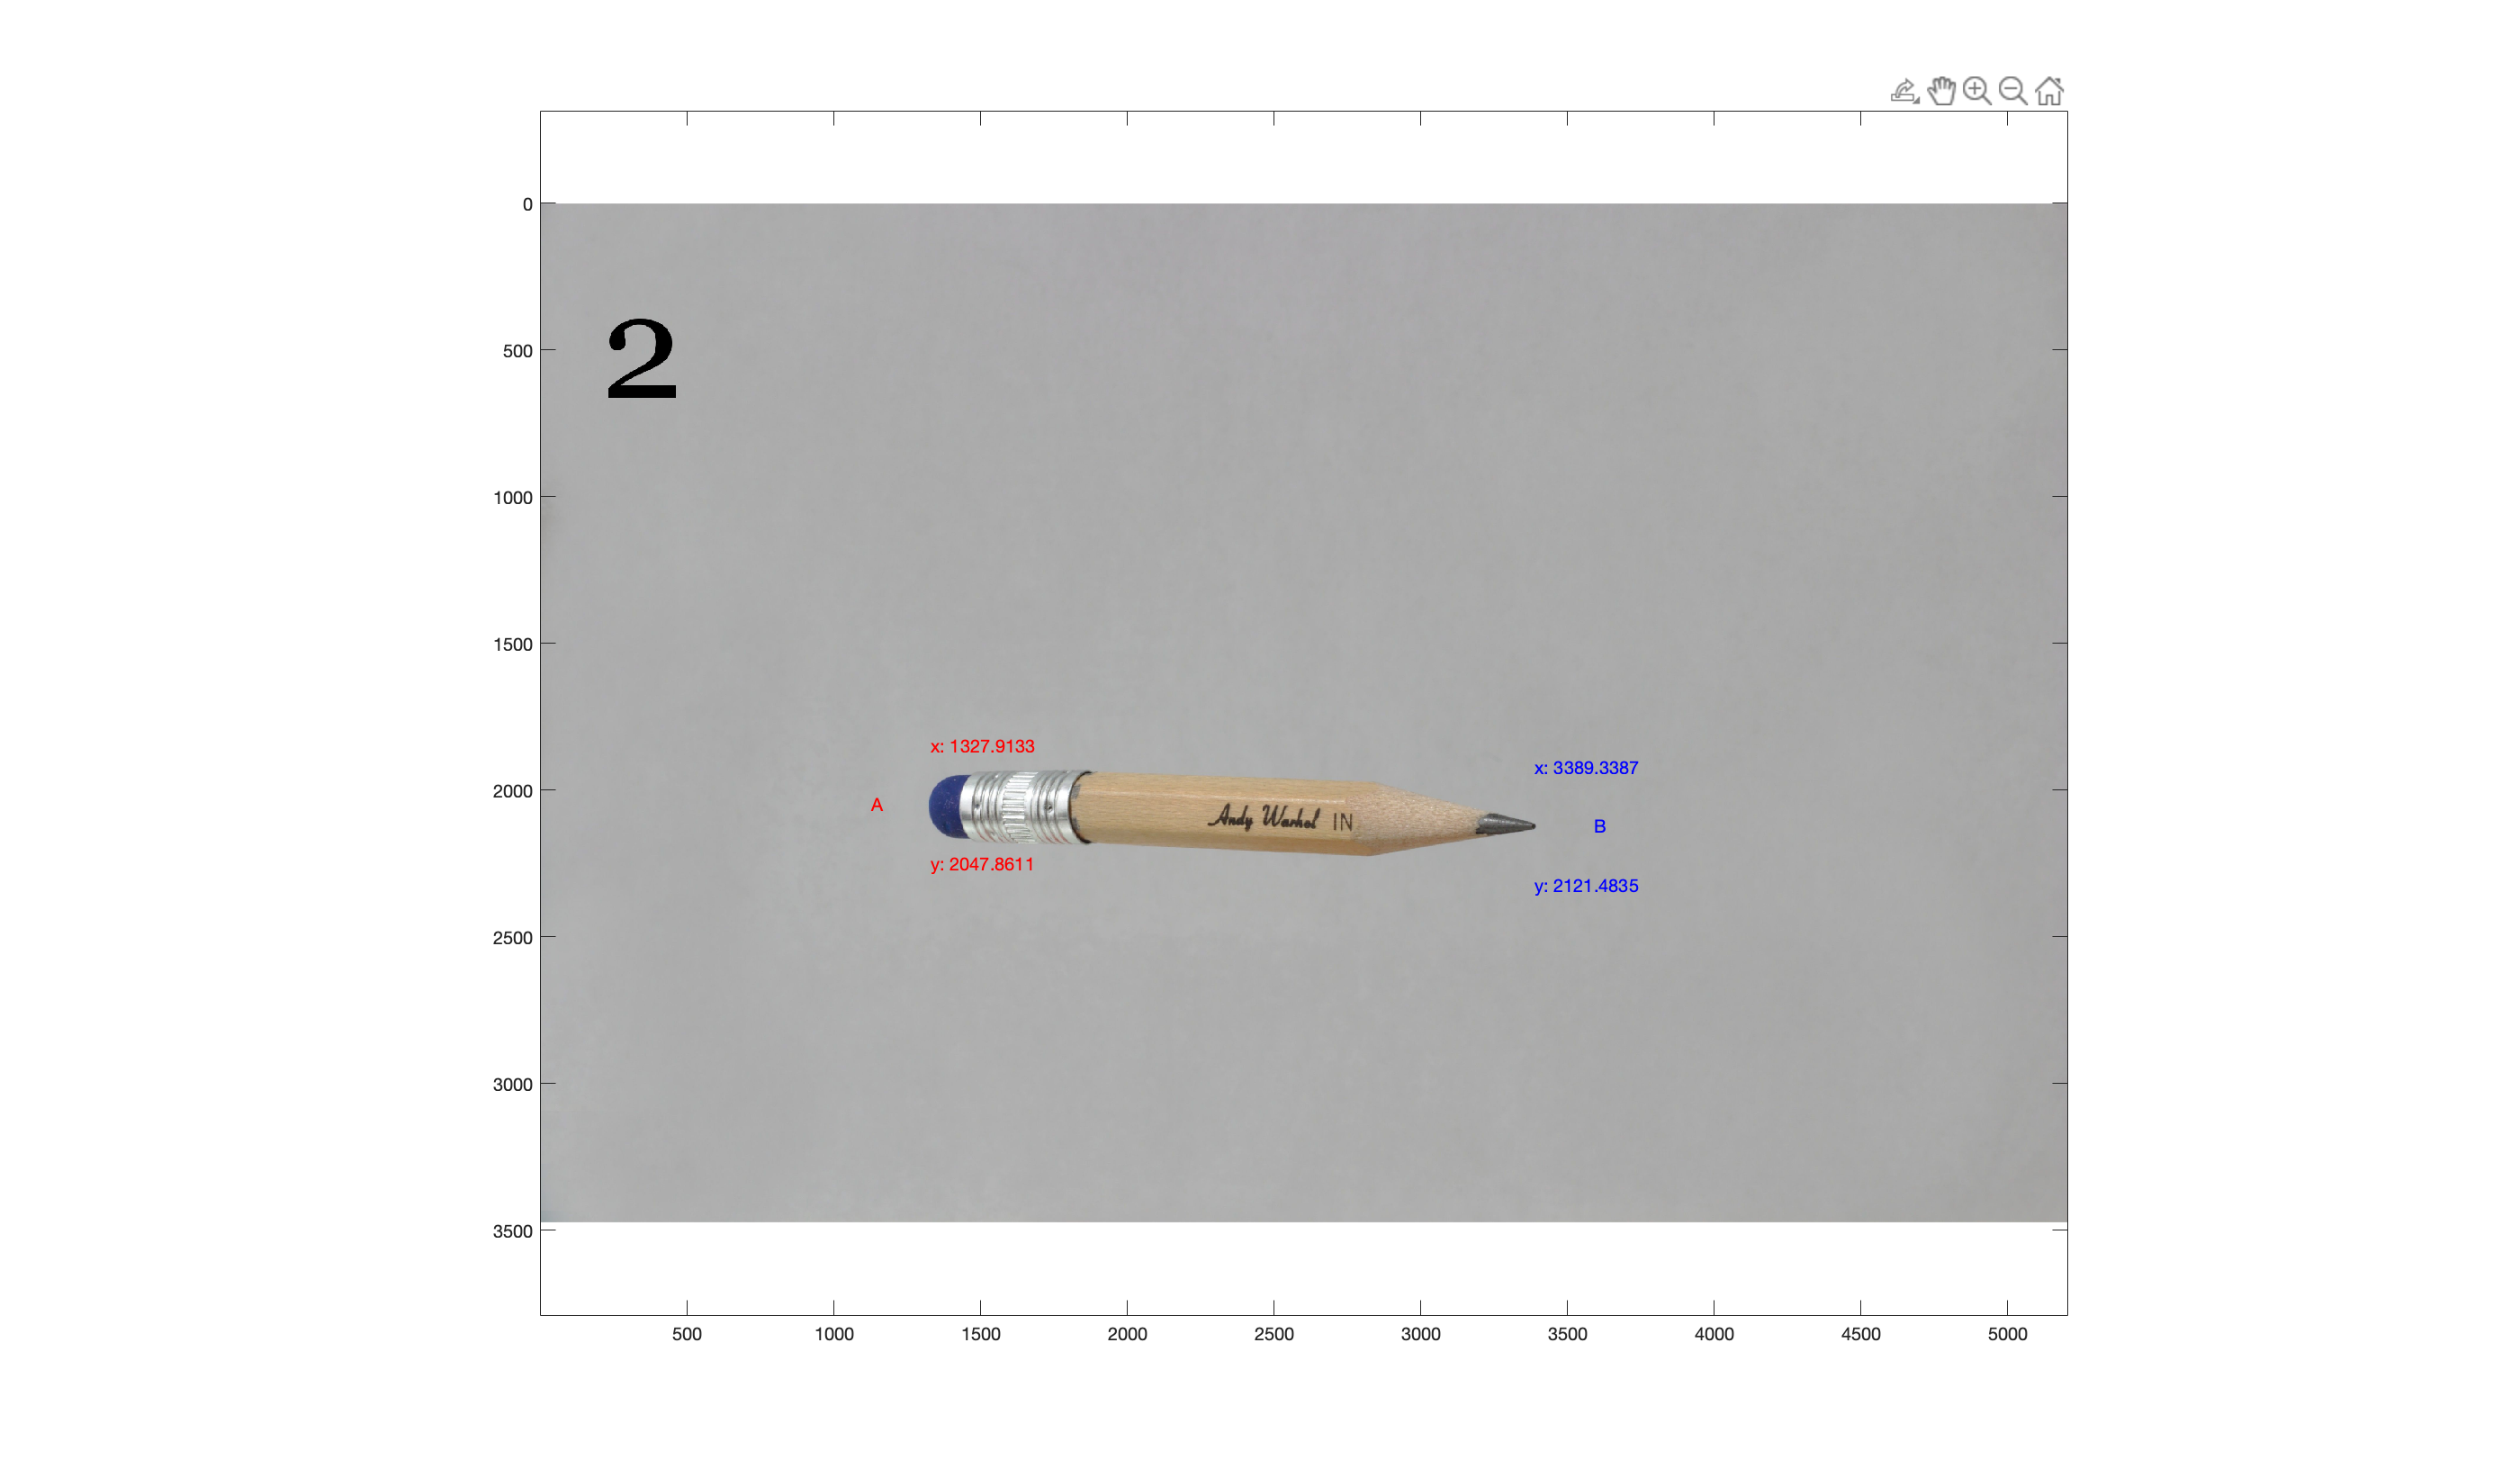

image_right = imread('C2.jpg'); % Read the 2 image from a file
h2=figure(1); % Create a new figure.
clf;
imagesc(image_right); % Plot an image.
axis('equal'); % Do not distort x and y axes.

% For capturing the pixel coordinates ginput() might be useful. Use of ginput()
% is easier, if you make the image a bit larger:
set(h2,'position',[0 100 1400 900]);

% Here pixel coordinates of both ends of the pensil from the second image are
% found
% x_pixel_A_2 - x pixel coordinate of A end of the pensil from the 2 image
% y_pixel_A_2 - y pixel coordinate of A end of the pensil from the 2 image
[x_pixel_A_2, y_pixel_A_2] = ginput(1);
text_x_str_A_2 = ['x: ' num2str(x_pixel_A_2)];
text_y_str_A_2 = ['y: ' num2str(y_pixel_A_2)];
text(x_pixel_A_2 - 200, y_pixel_A_2, 'A', 'Color', 'r');
text(x_pixel_A_2, y_pixel_A_2 - 200, text_x_str_A_2, 'Color', 'r');
text(x_pixel_A_2, y_pixel_A_2 + 200, text_y_str_A_2, 'Color', 'r');

% x_pixel_B_2 - x pixel coordinate of B end of the pensil from the 2 image
% y_pixel_B_2 - y pixel coordinate of B end of the pensil from the 2 image
[x_pixel_B_2, y_pixel_B_2] = ginput(1);
text_x_str_B_2 = ['x: ' num2str(x_pixel_B_2)];
text_y_str_B_2 = ['y: ' num2str(y_pixel_B_2)];
text(x_pixel_B_2 + 200, y_pixel_B_2, 'B', 'Color', 'b');
text(x_pixel_B_2, y_pixel_B_2 - 200, text_x_str_B_2, 'Color', 'b');
text(x_pixel_B_2, y_pixel_B_2 + 200, text_y_str_B_2, 'Color', 'b');

% Here the pixel coordinates of A and B ends of pensil from 2 image 
% are converted into camera's system coordinates

% camera coordinates of A end from 2 image
camera_A_2 = px2pos([x_pixel_A_2, y_pixel_A_2]);

% camera coordinates of B end from 2 image
camera_B_2 = px2pos([x_pixel_B_2, y_pixel_B_2]); 

## Define the camera coordinate systems and transform points from camera to the world coordinate system:

% The camera positions, r{1} and r{2}.
r = {[ ...
   -0.0509
   -0.0068
   -0.0113
], [
    0.0514
    0.0149
    0.0034
]};

% The camera orientations given in Cartesian coordinate system.
% R=[e_x e_y e_z], where e_i is the i:th coordinate axis expressed in some
% other cartesian system (in this case, the world coordinates).
R = {[ ...
    0.9955    0.0221   -0.0921
    0.0063    0.9549    0.2968
    0.0945   -0.2961    0.9505
], [ ...
    0.9784   -0.0641    0.1967
   -0.0047    0.9436    0.3311
   -0.2068   -0.3249    0.9229
]};

% In order to transform the coordinates from camera coordinate system to
% world coordinate system, I use the transformation matrixes

% coordinates of point A from camera 1 in world coordinates
world_A_1 = mtimes(R{1}, camera_A_1) + r{1};
% coordinates of point A from camera 2 in world coordinates
world_A_2 = mtimes(R{2}, camera_A_2) + r{2};

% coordinates of point B from camera 1 in world coordinates
world_B_1 = mtimes(R{1}, camera_B_1) + r{1};
% coordinates of point B from camera 2 in world coordinates
world_B_2 = mtimes(R{2}, camera_B_2) + r{2};


% Here is the calculation of the closest points of two lines: the first one is
% defined by world_A_1 and r1 points and the other line is defined by
% world_A_2 and r2 points 
distance_A = 1;
% maximum extention is estimated from the graph at the end
for extention_A_1 = 0:0.1:10
    for extention_A_2 =  0:0.1:10
        % Here we interate alond the lines using the extention factor to
        % extend the vectors that define the lines
        point_1_A = world_A_1 - extention_A_1 * (world_A_1 - r{1});
        point_2_A = world_A_2 - extention_A_2 * (world_A_2 - r{2}); 
        
        % Here is the standard procedure to find minimum distance between
        % two lines
        new_distance_A = norm(point_1_A - point_2_A);
        if new_distance_A < distance_A 
            distance_A = new_distance_A; 
            closest_point_1_A = point_1_A;
            closest_point_2_A = point_2_A;
        end
    end          
end 

% Here is the calculation of the closest points of two lines: the first one is
% defined by world_B_1 and r1 points and the other line is defined by
% world_B_2 and r2 points 
distance_B = 1;
for extention_B_1 = 0:0.1:10
    for extention_B_2 =  0:0.1:10
        point_1_B = world_B_1 - extention_B_1 * (world_B_1 - r{1});
        point_2_B = world_B_2 - extention_B_2 * (world_B_2 - r{2}); 
        
        new_distance_B = norm(point_1_B - point_2_B);
        if new_distance_B < distance_B 
            distance_B = new_distance_B; 
            closest_point_1_B = point_1_B;
            closest_point_2_B = point_2_B;
        end
    end          
end

% the calculation of length from 1 camera
length_1_camera = norm(closest_point_1_B - closest_point_1_A);
% the calculation of length from 2 camera
length_2_camera = norm(closest_point_2_B - closest_point_2_A);

% the calculation of the middle of the distance between the closest
% points
mid_distance_A = (closest_point_2_A + closest_point_1_A)/2;
mid_distance_B = (closest_point_2_B + closest_point_1_B)/2;
% the length as a distance from two middle distance of closest points 
length_mid = norm(mid_distance_A - mid_distance_B);

## Plot the camera locations and coordinate axes using given Matlab routines

Save the plot routines to some directory (preferably not the one, where you have this script) and set it to your Matlab path. We will use the same routines in later exercises, too. The plot routines assume 3D points given as row vectors, but this exercise (and coordinate transforms in general) use column vectors, so we'll have to transpose.

## Plot camera systems in world coordinates

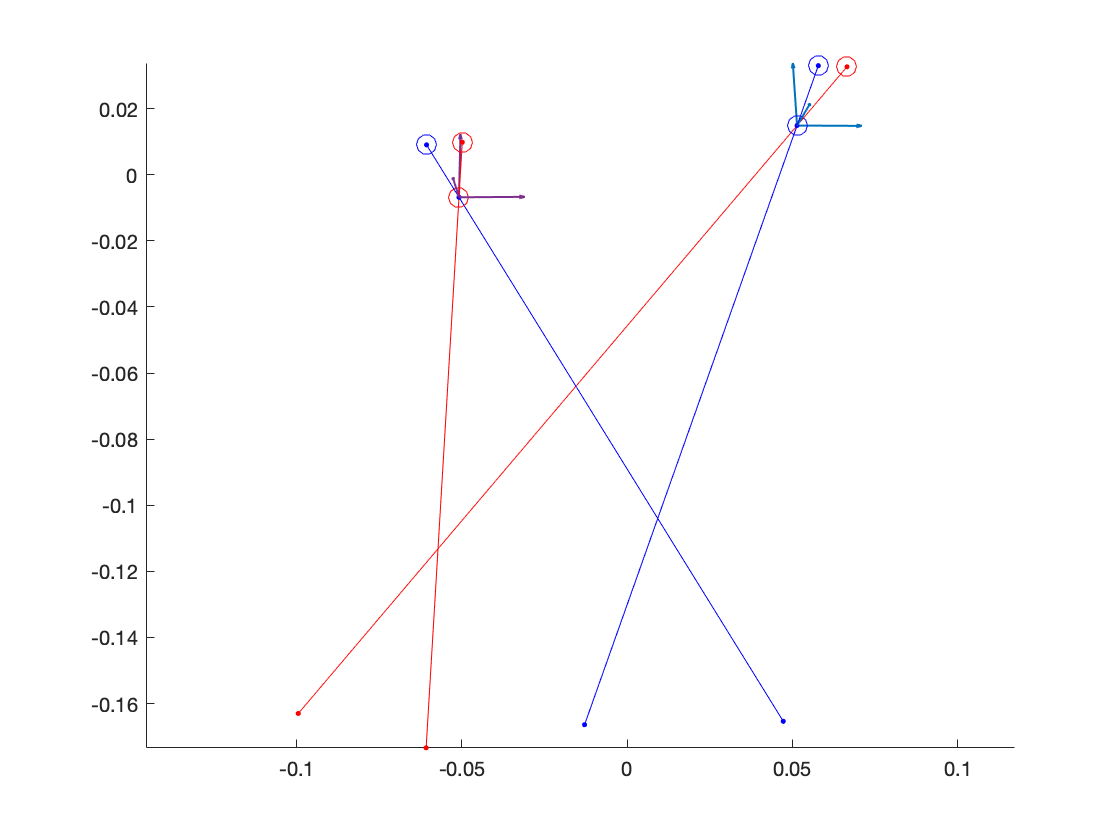

figure(2);clf;hold on

PlotPoints(r{1}','ro', 10);
PlotPoints(world_A_1', 'ro', 10);
PlotPoints(world_B_1', 'bo', 10);
PlotDipoles([r{1} r{1} r{1}]',.02*R{1}',1,0);

PlotPoints(r{2}','bo', 10);
PlotPoints(world_A_2', 'ro', 10);
PlotPoints(world_B_2', 'bo', 10);
PlotDipoles([r{2} r{2} r{2}]',.02*R{2}',1,0);

% Here I draw the line in order to estimate the position of intersection
pts_A_1 = [r{1}'; world_A_1'];
plot3(pts_A_1(:,1), pts_A_1(:,2), pts_A_1(:,3));
dP_A_1 = diff(pts_A_1) ;
% Extend line by 1 unit at botht ends 
t = 10;
point_ext_1 = -t*dP_A_1+r{1}' ;
pts_A_1 = [point_ext_1 ; r{1}' ; world_A_1'] ;
plot3(pts_A_1(:,1), pts_A_1(:,2), pts_A_1(:,3),'.-r')

pts_A_2 = [r{2}'; world_A_2'];
plot3(pts_A_2(:,1), pts_A_2(:,2), pts_A_2(:,3));
dP_A_2 = diff(pts_A_2) ;
% Extend line by 10 unit at botht ends 
point_ext_1 = -t*dP_A_2+r{2}' ;
pts_A_2 = [point_ext_1 ; r{2}' ; world_A_2'] ;
plot3(pts_A_2(:,1), pts_A_2(:,2), pts_A_2(:,3),'.-r')


pts_B_1 = [r{1}'; world_B_1'];
dP_B_1 = diff(pts_B_1) ;
% Extend line by 10 unit at botht ends 
point_ext_1 = -t*dP_B_1+r{1}' ;
pts_B_1 = [point_ext_1 ; r{1}' ; world_B_1'] ;
plot3(pts_B_1(:,1), pts_B_1(:,2), pts_B_1(:,3),'.-b')

pts_B_2 = [r{2}'; world_B_2'];
plot3(pts_B_2(:,1), pts_B_2(:,2), pts_B_2(:,3));
dP_B_2 = diff(pts_B_2) ;
% Extend line by 1 unit at botht ends 
point_ext_1 = -t*dP_B_2+r{2}' ;
pts_B_2 = [point_ext_1 ; r{2}' ; world_B_2'] ;
plot3(pts_B_2(:,1), pts_B_2(:,2), pts_B_2(:,3),'.-b')


axis equal